# Plotting LIDAR Range Data

Objective: This script reads the LIDAR data from the CreateRobot object (robotObj) and plots the raw output for evaluation. The LIDAR range is the distance an obstacle is away from the sensor at the corresponding LIDAR angle.

Cheat Sheet: In this script, you will use the following functions and CreateRobot properties:

- CreateRobot.angRangeLidar: Angular range of LIDAR sensor

- CreateRobot.rangeLidar: Linear range of LIDAR sensor

- CreateRobot.numPtsLidar: Number of points in LIDAR sensing range

- CreateRobot.angleArray: Array of LIDAR angles

- genLidar(CreateRobot): Generates a reading for the LIDAR sensor

For more information on these functions an properties, refer to the CreateRobot documentation 

help CreateRobot %in Command Window

  Creates definition of class, instances of which will include all
  properties and controls associated with a single CreateRobot robot

    Documentation for CreateRobot



Helper Functions used in this exercise:

- *plot_lidar:* plots the LIDAR output (range vs. angle)

Exercise:

Using the Simulator, get the CreateRobot object that represents the current state of the robot (Using "Read Sensors"). Complete the code below to read the LIDAR data from the variable **robotObj**. 

**LIDAR sensor: **On the Create, the LIDAR sensor is situated directly on the edge of the robot directly in front (along the x-axis of the robot frame) and is oriented in the same direction. This is what defines the origin of the sensor reference frame. 

Complete the code below to 

- Initialize robot constraints based on the CreateRobot and sensor configuration. 

- Read the LIDAR sensor

**COMPLETE THE CODE BELOW**

%1. Initialize, get LIDAR Constants
angRangeLidar = robotObj.angRangeLidar; %Insert your code here
rangeLidar = robotObj.rangeLidar;%Insert your code here
numPtsLidar = robotObj.numPtsLidar;%Insert your code here
angleArray= robotObj.angleArray; %Insert your code here


% 2. Get LIDAR data
distLidar= genLidar(robotObj, map);%Insert your code here


. 

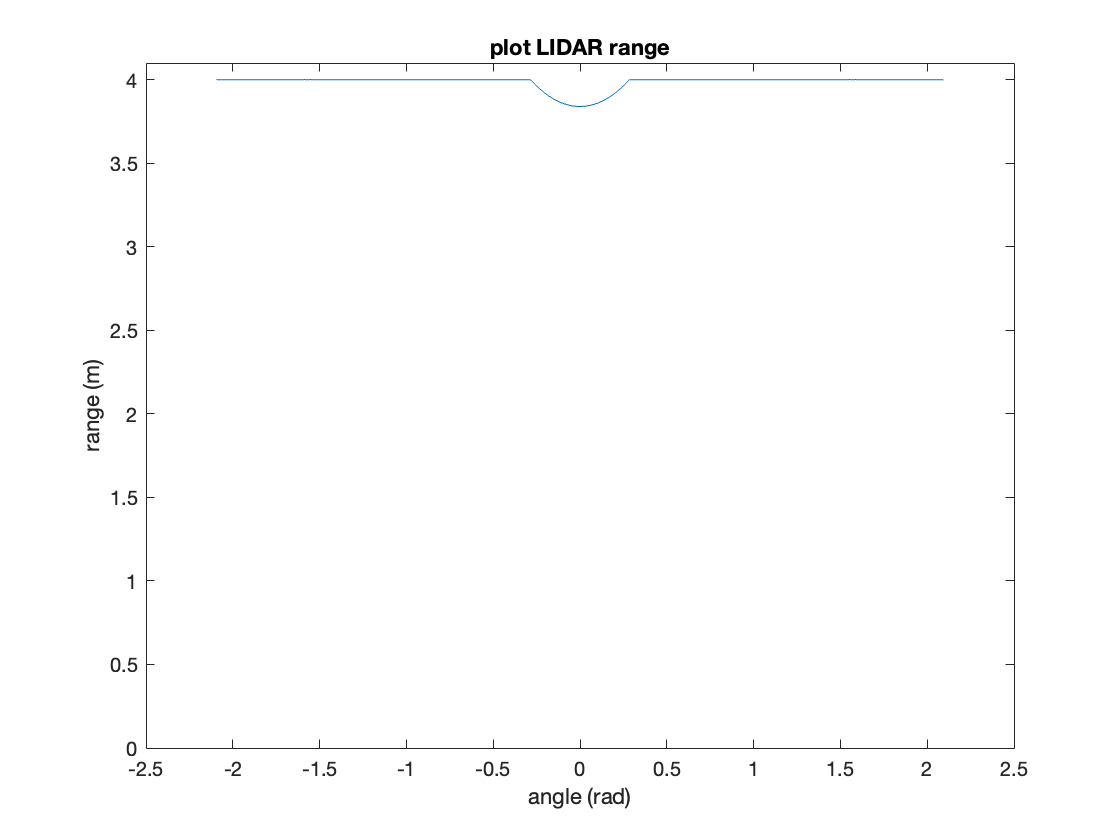

% --- Plot ----
plot_lidar(angleArray, distLidar); 

Expected Results: If you've read the LIDAR information correctly from the CreateRobot object, the plot will show the raw LIDAR range vs. the LIDAR angle. LIDAR angle 0 represents the LIDAR reading directly in front of the robot. Does the range output correspond to the estimated distance of an object directly in front of the robot?

Check your Comprehension:

Move the robot around the map facing different obstacles and rerun this exercise. Does the range output make sense based on where you place the robot? What if no walls are in the field of view (sensor footprint) of the LIDAR, what happens?